#  Linear Regression:

The data in the accompanying table relate heart rate at rest Y to kilograms body weight X.

clear all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53


**Q: Graph these data. Does it appear that there is a linear relationship between body weight and heart rate at rest?**

A:

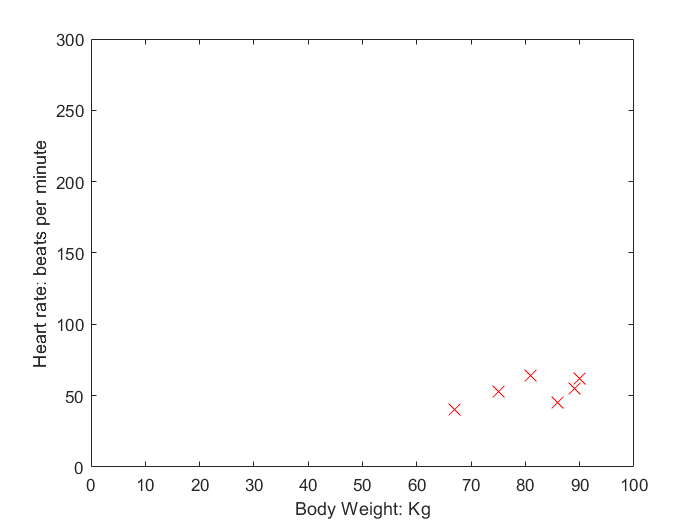

plot_data(X,Y)

Yes, a direct linear relationship.

## Q: Compute a, b and write the regression equation for these data. Plot the regression line on the graph. Interpret the estimated regression coefficients.

A:

close all
Theta = normal_equation(X,Y)

Theta =     4.7990
    0.5947


points = linspace(min(X)-30,max(X)+30,10);

line = predict(points, Theta);

J = cost_function(X, Y', Theta); %% error

J = 2.5461e-25

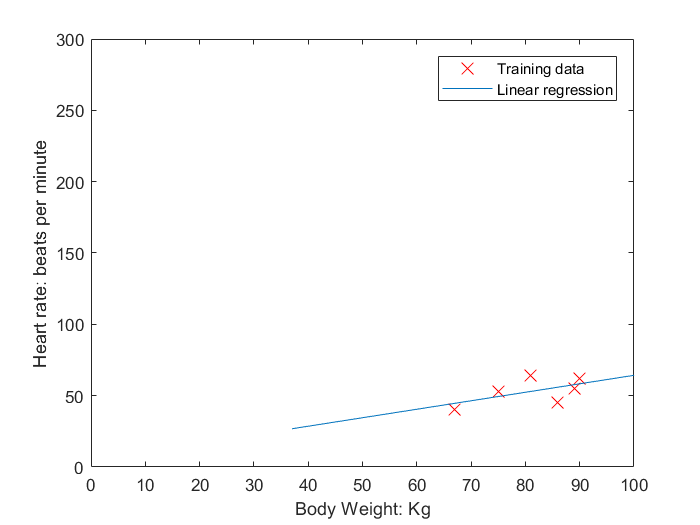


plot_data(X, Y);hold on
plot(points,line, '-');hold off
plot(mean(X))
legend('Training data', 'Linear regression')

 Theta $\theta=(4.799; 0.5947)$ are the coeficients of the Hypotesis $h(x,\theta) = \theta_0 * x_0 + \theta_1 * x_1$ being $x_0$ the bias term = 1. This hypotesis represent a linear equation so $\theta_0$ is the point where the line cuts the y axis. $\theta_1$ is a factor that represents how important is the feature X.

## Q: Now examine the data point(67, 40). If this data point were removed from the data set, what changes would occur in the estimates of a and b $(\theta)$?

A:

clear all;

newX = [90, 86, 89, 81, 75]

newX =     90    86    89    81    75


newY = [62, 45, 55, 64, 53]

newY =     62    45    55    64    53



Theta = normal_equation(newX, newY)

Theta =    49.1641
    0.0788


The point is the min value of the function, so the $\theta$ changes a lot. The line has de capacity of change the slope adapting better to the new form of the data, in this case decreasing the slope, so $\theta_0$ has a higher value and $\theta_1$ as a lower value.

## Q: Predict the hear rate for a particular subject whose weight is 80 kilograms.

A:

clear all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53



Theta = normal_equation(X, Y);
cost_function(X(6),Y(6)',Theta)

J = 6.4788

ans = 6.4788

predict(83.5,Theta)

ans = 54.4551

The anwser is $\approx$ 52.

**Q: Whithout doing the computations, for which measured X would the corresponsing Y have the smallest error? Why?**

A:

**Q: What would happen if you apply a polynomial fitting **$y = ax^2 + bx = c$** ?**

A:

clear all, close all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53



X = repmat(X,2,1);
X(2,:)= X(2,:).^2;

Theta = normal_equation(X, Y)

Theta =  -339.1338
    9.4225
   -0.0560


points = repmat(linspace(1,100,100),2,1);
points(2,:) = points(2,:).^2;
line = predict(points, Theta)

line =  -329.7673
 -320.5128
 -311.3702
 -302.3396
 -293.4209
 -284.6142
 -275.9195
 -267.3367
 -258.8659
 -250.5071


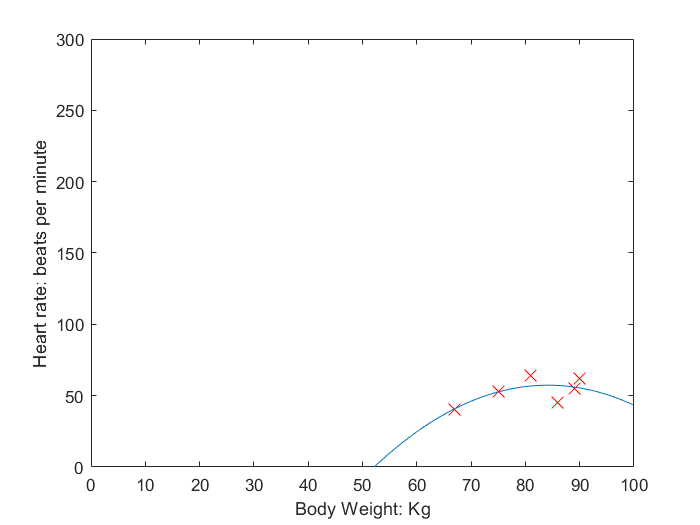

plot_data(X,Y), hold on
plot(points(1,:), line)

Now your fitting is using a univariate polynomial quadradict function. There is no line anymore.

**Q: And computing this fitting **$y = ax^3 + bx^3 + cx + d$** ?**

**A:**

clear all, close all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53



X = repmat(X,3,1);
points = repmat(linspace(1,100,100),3,1);


for i =2:3
    X(i,:)= X(i,:).^i;
    points(i,:) = points(i,:).^i;
end

Theta = normal_equation(X, Y)

Theta =    -0.1295
   -3.3528
    0.1034
   -0.0007



line = predict(points, Theta)

line =    -3.3796
   -6.4268
   -9.2751
  -11.9285
  -14.3909
  -16.6662
  -18.7585
  -20.6716
  -22.4096
  -23.9763


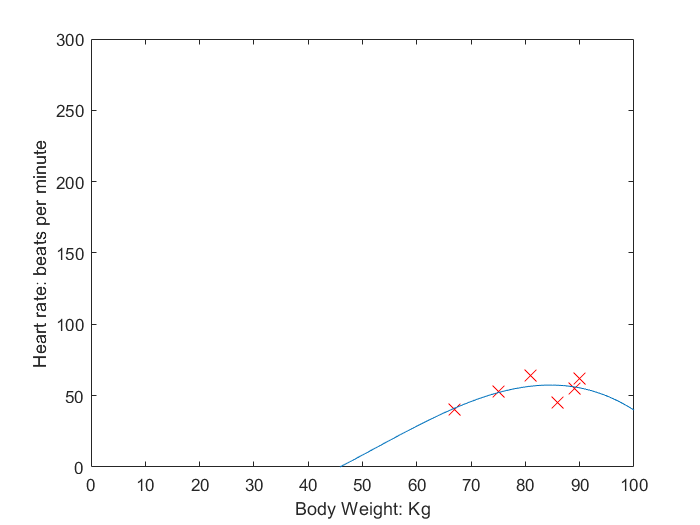

plot_data(X,Y), hold on
plot(points(1,:), line)

Now, our model fit a polynomial cubic univariate function.

**Q: Calculate the operation **$\frac{1}{y^2}$** to obtain a new **$y$** vector and compute a new fitting **$h(x,\theta) = \theta_0 * e^{\theta_1*x}$

A:

clear all, close all
X = [90, 86, 67, 89, 81, 75];
oldY= [62, 45, 40, 55, 64, 53]; 
Y = 1./(oldY.^2)

Y =    1.0e-03 *

    0.2601    0.4938    0.6250    0.3306    0.2441    0.3560



Ychanged = log(Y);
Theta = normal_equation(X, Ychanged)

Theta =    -5.9538
   -0.0242


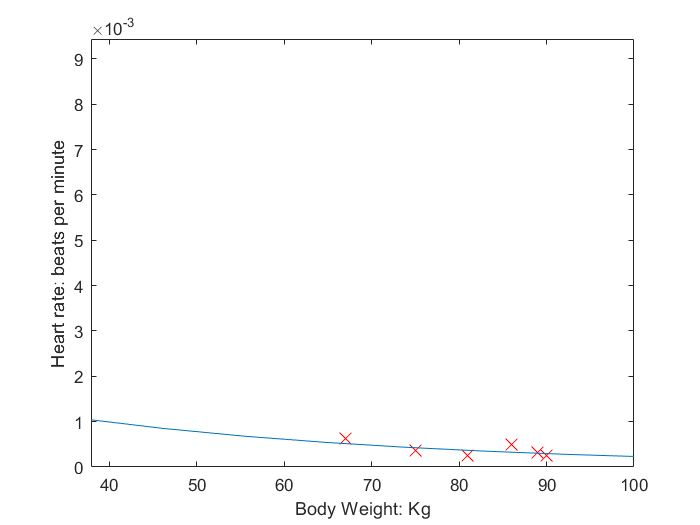

Theta(1) = exp(Theta(1));
points = linspace(min(X)-30,max(X)+30,10);

plot_data(X,Y), hold on
plot(points, Theta(1) * exp(Theta(2)*points));

xlim([37.9 100.0])
ylim([0.00000 0.00944])

**Q: Calculate the operations (rewrite your dataset) **$X2 = \frac{x}{100}$** and **$y = 5*X2*e^{4*X2}$** and compute a new fitting using **$h(x,\theta)=\theta_0 * x * e^{\theta_1*x}$**.**

**Which are the values of **$\theta$**? Are they **$\theta_0= 5$** and **$\theta_1=4$**? Why?**

**A:**

clear all, close all

X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53


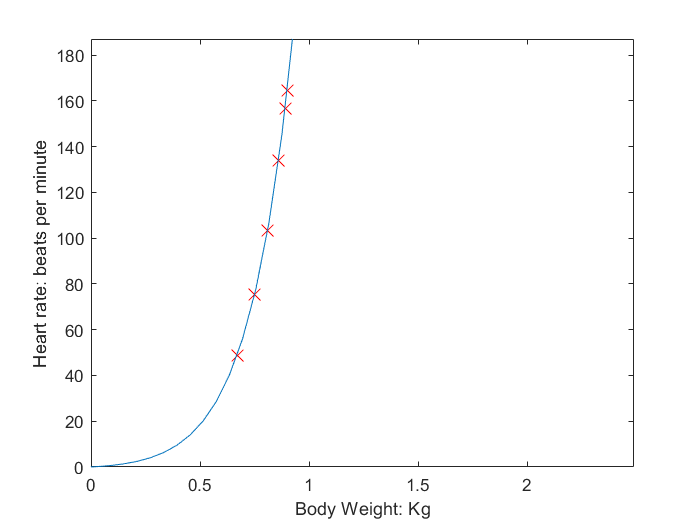

X = X/100;
Y = 5*X.*exp(4*X);


Ychanged = log(Y./X);
Theta = normal_equation(X,Ychanged);

Theta(1) = exp(Theta(1));

points = linspace(min(X)-30,max(X)+30,1000);

plot_data(X,Y), hold on
plot(points, Theta(1)*points .* exp(Theta(2)*points));

xlim([0.00 2.49])
ylim([0 187])

Yes they are, and its normal, we generate the data using a function with 5 and 4 as parameters.